## Assigment-Q8

#### Q8

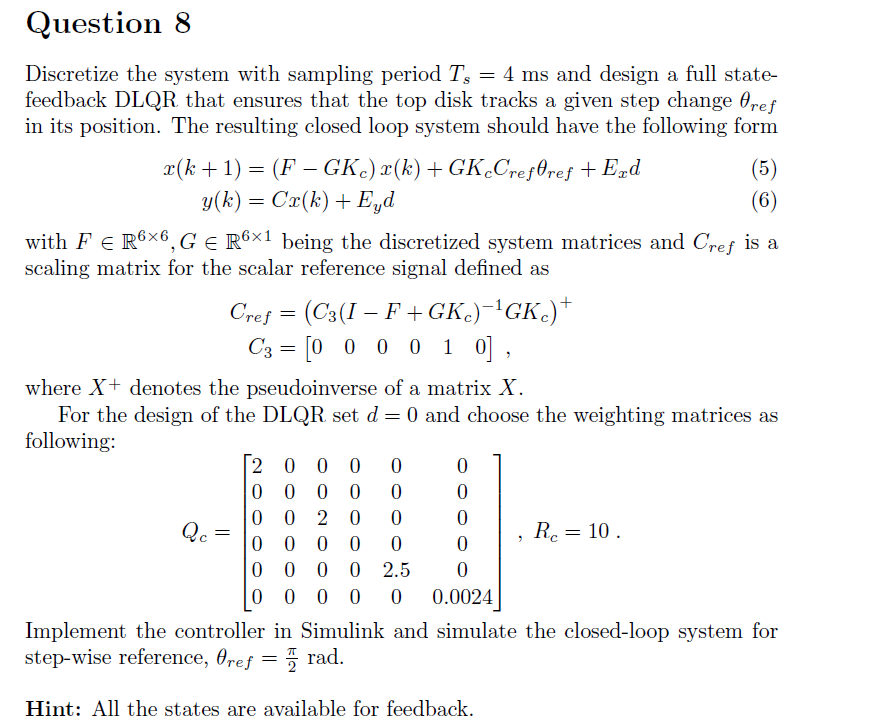

clear all
close all;
clc;
load('ECP_values.mat');

%Q8 data:

Ts=0.004        %sampling period

Ts = 0.0040

d=0;            %no disturbances
theta_3_ref=pi/2; %reference: top disc tracks a reference, theta_3

% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s


%% State space representation
A = [0 1 0 0 0 0;
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0;
    0 0 0 1  0 0;
    k_1/J_2 0 (-k_1-k_2)/J_2 -b_2/J_2 k_2/J_2 0;
    0 0 0 0 0 1;
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 1/J_1 0 0 0 0]';
C = [ 1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];
D = 0;
E_x = [0 -1/J_1 0 0 0 0]';
E_y = [0 0 0]';

%system discretization
sys_ss=ss(A,B,C,D);
sys_ssd=c2d(sys_ss,Ts);

F=sys_ssd.A;
G=sys_ssd.B;

%discrete LQR controller design:

Qc=[2 0 0 0 0 0;
   0 0 0 0 0 0;
   0 0 2 0 0 0;
   0 0 0 0 0 0;
   0 0 0 0 2.5 0;
   0 0 0 0 0 0.0024]; %Q8 data

Rc=10;                %Q8 data

[Kc,S,eig_CL]=dlqr(F,G,Qc,Rc); %DLQR controller design

%Cref matrix: scaling matrix for the scalar reference signal

C3=[0 0 0 0 1 0];
Cref=pinv(C3*inv(eye(size(F,1))-F+G*Kc)*G*Kc)

Cref =     1.2451
    0.1117
    0.1738
    0.0495
    0.2337
    0.0511



%Simulation
ans=sim('Q8_Simulink.slx')

ans =   Simulink.SimulationOutput:

                    ref: [1x1 struct] 
                   tout: [2503x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



%plots

fig=figure

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


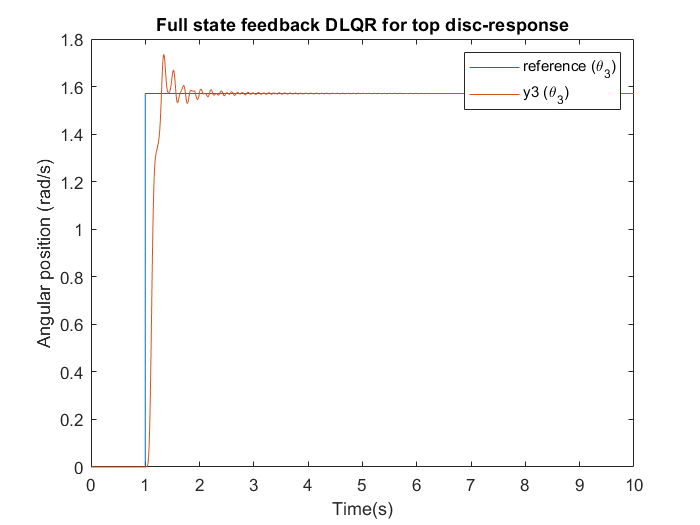

plot(ans.ref.time,ans.ref.signals.values,ans.y.time,ans.y.signals.values(:,3))
title('Full state feedback DLQR for top disc-response')
ylabel('Angular position (rad/s)')
xlabel('Time(s)')
legend('reference (\theta_3)','y3 (\theta_3)')
saveas(fig,'q8.png')

Conclusion:

In the plot can be seen that the output y3, corresponding to theta 3, incremental position encoder for the top disc, follows the reference value of pi/2.